# EJERCICIOS TEMA 2

1. Sea f(x) = (3 + x) cos. Use el polinomio interpolador de Lagrange cuadr´atico con nodos x0 = 0, x1 = 1 y x2 = 3 para aproximar f(2), f(2.4), f(3.5) y f(4).


f = @(x) (3+x).*cos(pi*x*0.25).^2; %función conocida o a comparar con la interpolación
xi = [0 1 3 ];
 fi = f(xi); % si función conocida


x = [2 2.4 3.5 4]; %puntos en los que obtener evaluado el pol interpolador
p = 0*x; 

for i=1:length(xi) 
    li=0*x+1;

    for j=1:length(xi)
        if i ~= j
         li = li.*(x-xi(j))/(xi(i)-xi(j));
        end
    end

    p = p + fi(i)*li 

end

p =    -1.0000   -0.8400    1.2500    3.0000


p =     1.0000    0.6000   -0.5000   -1.0000


p =     2.0000    2.2800    3.8750    5.0000



%ahora directamente miro p que será un vector en esos puntos

2 Escriba, para las siguientes funciones f(x), el t´ermino del error E2(x) del polinomio interpolador de Lagrange cuadr´atico con nodos x0 = −1, x1 = 1 y x2 = 3. (a) f(x) = 4x 2 − 3x + 2 (b) f(x) = x 3 − 2x 2 + 1

%al estar equiespaciados utilizaremis la expresión del error que
%conocemos; hazlo en el cuaderno vaga!! (n=2 así que hanrá que hacer el máximo
% de la tercera derivada)  h=2

%¿en el primero será 0???? ya que la tercera derivada es 0 wei

f = @(x) x.^3 -2*x.^2 ; %función conocida o a comparar con la interpolación
xi = [0 0.5 1 ];

fi = f(xi); % si función conocida


x = 0:0.01:1; %puntos en los que obtener evaluado el pol interpolador
p = 0*x; 

for i=1:length(xi) 
    li=0*x+1;

    for j=1:length(xi)
        if i ~= j
         li = li.*(x-xi(j))/(xi(i)-xi(j));
        end
    end

    p = p + fi(i)*li; 

end

hold on 
%plotplot(x,f(x),'b') %representar función 
plot(x,p,'g')
%scatter(xi, fi, 'r')

4

Halla el polinomio de Lagrange de f(x) = 1/x, x ∈ [2, 4], utilizando los nodos x0 = 2, x1 = 2.75 y x2 = 4. Determina la forma de error de este polinomio y el m´aximo error que se comete al aproximar f en el intervalo [2, 4].

%A mano
%datos de entrada
xi= [2 2.75 4];
f=@(x) 1./x;
fi = f(xi);
%fi= [0.5103757 0.5207843 0.5104147 0.4813306 0.4359160];
n=length(xi);
dd=zeros(n); %reservamos espacio
dd(:,1)=fi    %sabemos que la primera columna de la matrizserán las imágenes de los puntos

dd =     0.5000         0         0
    0.3636         0         0
    0.2500         0         0



%matriz de diferencias divididas:
for j=2:n
    for i=1:n-j+1
        dd(i,j)=(dd(i+1,j-1)-dd(i,j-1))/(xi(i+j-1)-xi(i));
    end
end
dd

dd =     0.5000   -0.1818    0.0455
    0.3636   -0.0909         0
    0.2500         0         0


ai=dd(1,:);

for i=1:length(ai)

    fprintf('a%d = %d \n',i,ai(i));

end

a1 = 5.000000e-01 
a2 = -1.818182e-01 
a3 = 4.545455e-02 


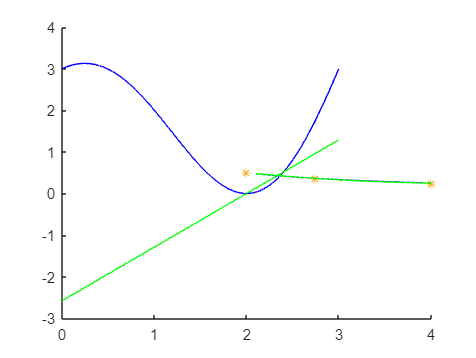


%dibujo
x = 2.1:0.001:4; %puntos en los que obtener el polinomio p evaluado


p = 0*x;
q = 1;

for i=1:n
        p = p + ai(i).*q; %construcción p 
        q = q.*(x-xi(i)); 
end

hold on 
%plot(xi,fi, '*')  %representar datos dados
plot(x,f(x),'b') %representar función 
plot(x,p,'g') %representar polinomio interpolador

% xlim([2 2.8])
% ylim([0.4 0.6])


15

f=@(x)

Invalid expression. Check for missing or extra characters.

xi=

